# **Ítem II. Preguntas de desarrollo**

## 1.-    Un robot móvil parte del reposo y sigue una trayectoria lineal con una aceleración constante de 0.5 m/s² durante 10 segundos. 

a) Calcula la velocidad final del robot. (5 pts)

b) Determina la distancia total recorrida. (5 pts)

## 2.-    Un brazo robótico en una línea de montaje mueve una pieza de un punto A a un punto B, separados por 1.5 metros, en un movimiento uniformemente acelerado. Si el tiempo total del movimiento es de 3 segundos, calcule:  

a) La aceleración necesaria. (5 pts)

b) La velocidad máxima alcanzada durante el movimiento. (5 pts)

# Desarrollo


$$v=v_0 +at$$



$$x=v_0 t+\frac{1}{2}at^2$$


## 1)

clc; clear all;
vi=0;
a=0.5;
t=10;
vf=vi+a*t;

disp(['El valor final de la velocidad del primer robot es: ' num2str(vf)]);

El valor final de la velocidad del primer robot es: 5


x=vi*t+(1/2)*a*t^2;
disp(['La distancia recorrida por el primer robot es de: ' num2str(x)]);

La distancia recorrida por el primer robot es de: 25


## 2)


$$\frac{\left(x-v_0 t\right)*2}{t^2 }=a$$


clc; clear all;
vi=0;
x= 1.5;
t=3;
a=(2*(x-vi*t))/t^2;
disp(['La aceleracion del Segundo robot es de: ' num2str(a)]);

La aceleracion del Segundo robot es de: 0.33333



vf=vi+a*t;
disp(['El valor final de la velocidad del segundo robot es: ' num2str(vf)]);

El valor final de la velocidad del segundo robot es: 1


## 3.-     Se tiene un robot KUKA KR6 R900 de 6 grados de libertad, en el cual se entrega los siguientes datos: 

- Longitudes de los brazos (𝑎): [0, 0.26, 0.68, 0.035 ,0 ,0] metros

- Ángulos de twist (torsión) (𝛼): [𝜋/2, 0, 0, 𝜋/2, −𝜋/2,0] radianes

- Desplazamiento a lo largo del eje z (d): [0.4,0,0,0.67,0,0.158] metros

- Ángulos de las articulaciones (𝜃): se asume inicialmente en ceros, pero se reemplazarán por la configuración específica del ejercicio

- Las articulaciones que tendrá el robot en su funcionamiento son las siguientes: q = [pi/6, -pi/4, pi/3, 0, pi/4, pi/2];

- Velocidades de las articulaciones= [0.1, 0.2, -0.1, 0.05, -0.05, 0.1];

Con respecto a lo anterior cree un código en MATLAB que realice los cálculos descritos y muestre las velocidades lineales y angulares del efector final del robot, además de su matriz jacobiana y cómo estas afectan el movimiento y la precisión del efector final. (30 pts)

clc; clear all;
% Define los parámetros Denavit-Hartenberg del robot
a = [0, 0.26, 0.68, 0.035 ,0 ,0]; % Longitud del brazo
alpha = [pi/2, 0, 0, pi/2, -pi/2, 0]; % Ángulo alrededor de x
d = [0.4,0,0,0.67,0,0.158]; % Desplazamiento a lo largo de x
theta = [0, 0, 0, 0, 0, 0]; % Ángulo alrededor de z

% Crear el robot usando SerialLink
robot = SerialLink([theta; d; a; alpha]', 'name', 'Robot 6DOF');

% Configuración de articulaciones (en radianes)
q = [pi/6, -pi/4, pi/3, 0, pi/4, pi/2];

% Calcular la matriz jacobiana para la configuración dada
J = robot.jacob0(q);

% Velocidades de las articulaciones ejemplo (en rad/s)
q_dot = [0.1, 0.2, -0.1, 0.05, -0.05, 0.1];

% Calcular las velocidades del efector final usando la matriz jacobiana
vel_efector = J * q_dot';

% Mostrar la matriz jacobiana
disp('Matriz Jacobiana:');

Matriz Jacobiana:


disp(J);

    0.2937    0.0240   -0.1352    0.0172   -0.1493         0
    1.0547    0.0139   -0.0781    0.0099    0.0428         0
    0.0000    0.7666    0.5827   -0.0741   -0.0289         0
   -0.0000    0.5000    0.5000    0.5000    0.2241   -0.2380
   -0.0000   -0.8660   -0.8660   -0.8660    0.1294   -0.9539
    1.0000    0.0000    0.0000    0.0000   -0.9659   -0.1830




% Mostrar las velocidades del efector final
disp('Velocidades del efector final (lineales y angulares):');

Velocidades del efector final (lineales y angulares):


disp(vel_efector);

    0.0560
    0.1144
    0.0928
    0.0400
   -0.2318
    0.1300



## 4.-    Se tiene un Robot ABB IRB120 de 6 grados de libertad en el cual se necesitan determinar los siguientes parámetros:

- Longitudes de los brazos (𝑎):

- Ángulos de twist (torsión) (𝛼):

- Desplazamiento a lo largo del eje z (d):

- Ángulos de las articulaciones (𝜃)

- Determine las articulaciones que tendrá el robot en su estado inicial. Para eso puede tomar la posición inicial con el software Robot Studio.

- Determine velocidades de las articulaciones.

- De lo anterior, defina los parámetros de Denavit – Hartenberg para representar la cadena cinemática del robot.

En MATLAB que realice los cálculos descritos y muestre las velocidades lineales y angulares del efector final del robot, además de su matriz jacobiana y cómo estas afectan el movimiento y la precisión del efector final. (30 pts)

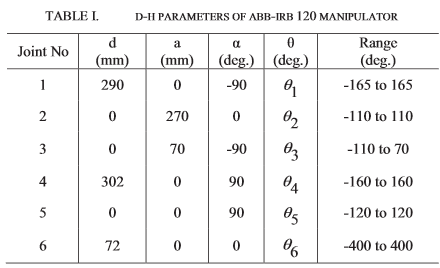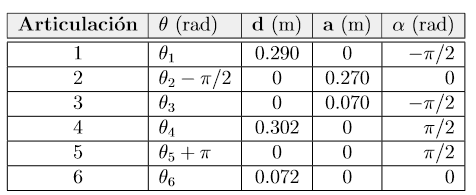

Recuperado de: G. Rajkumar, G. Bhramam and M. Sreekumar, "Coupled Differential Motion of ABB-IRB120 Manipulator for Kinematic Calibration in Image Acquisition," 2018 IEEE International Conference on Robotics and Biomimetics (ROBIO), Kuala Lumpur, Malaysia, 2018, pp. 2119-2124

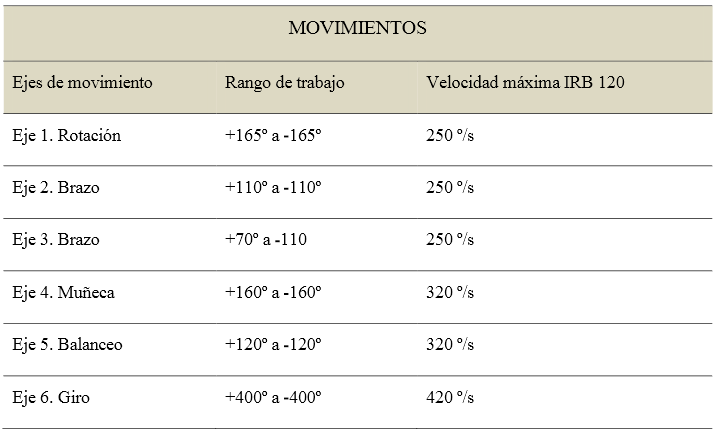

Recuperado de: MODELADO, PROGRAMACION YSIMULACIÓN DEL ROBOT IRB 120 DE ABB CON ROBOTSTUDIO, Beatriz Matos Agudo, Dep. Ingenieria de Sistemas y Automática Escuela Técnica Superior de Ingeniería Universidad de Sevilla, 2017

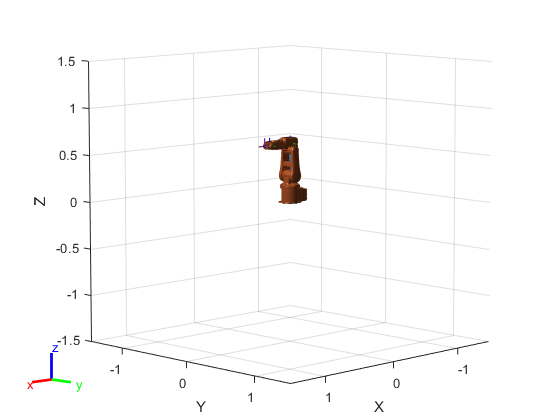

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


clc; clear all;
irb=loadrobot("abbIrb120");
show(irb)

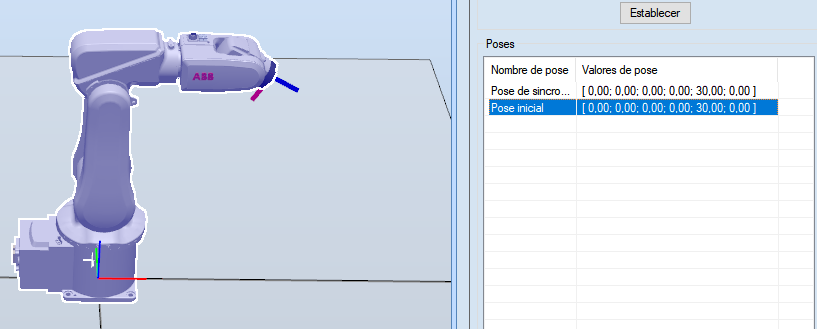

## Metodo 1: Trayectoria directa con transformacion Homogenea con objetivo hipotetico

clc; 
clear all;

% Define los parámetros Denavit-Hartenberg del robot
a = [0, 0.27, 0.07, 0, 0, 0]; % Longitud del brazo (en metros)
alpha = [-pi/2, 0, -pi/2, pi/2, pi/2, 0]; % Ángulo alrededor de x
d = [0.290, 0, 0, 0.302, 0, 0.072]; % Desplazamiento a lo largo de x (en metros)
theta = [0, 0, 0, 0, 0, 0]; % Ángulo alrededor de z
q_dot = [250*pi/180, 250*pi/180, 250*pi/180, 320*pi/180, 320*pi/180, 420*pi/180]; % Velocidades de las articulaciones (en radianes por segundo)

% Configuración de articulaciones (inicial)
q = [0, 0, 0, 0, pi/6, 0]; % Ángulos de las articulaciones (en radianes)

% Calcula la transformación homogénea (cinemática directa)
T = eye(4); % Inicializa la matriz de transformación homogénea
for i = 1:numel(q)
    A = [cos(q(i)), -sin(q(i))*cos(alpha(i)), sin(q(i))*sin(alpha(i)), a(i)*cos(q(i));
         sin(q(i)), cos(q(i))*cos(alpha(i)), -cos(q(i))*sin(alpha(i)), a(i)*sin(q(i));
         0, sin(alpha(i)), cos(alpha(i)), d(i);
         0, 0, 0, 1];
    T = T * A;
end

% Deriva la transformación homogénea para obtener la velocidad del efector final
Jv = zeros(3, 6); % Inicializa la matriz jacobiana lineal
Jw = zeros(3, 6); % Inicializa la matriz jacobiana angular

for i = 1:numel(q)
    % Calcula la matriz de rotación y translación para la articulación i
    A = [cos(q(i)), -sin(q(i))*cos(alpha(i)), sin(q(i))*sin(alpha(i)), a(i)*cos(q(i));
         sin(q(i)), cos(q(i))*cos(alpha(i)), -cos(q(i))*sin(alpha(i)), a(i)*sin(q(i));
         0, sin(alpha(i)), cos(alpha(i)), d(i);
         0, 0, 0, 1];
    
    % Calcula la matriz de transformación homogénea hasta la articulación i
    Ti = eye(4);
    for j = 1:i
        Ti = Ti * [cos(q(j)), -sin(q(j))*cos(alpha(j)), sin(q(j))*sin(alpha(j)), a(j)*cos(q(j));
                   sin(q(j)), cos(q(j))*cos(alpha(j)), -cos(q(j))*sin(alpha(j)), a(j)*sin(q(j));
                   0, sin(alpha(j)), cos(alpha(j)), d(j);
                   0, 0, 0, 1];
    end
    
    % Calcula el vector de rotación de la articulación i
    zi = Ti(1:3, 3);
    
    % Calcula el vector desde el origen del sistema de coordenadas hasta la articulación i
    pi = Ti(1:3, 4);
    
    % Calcula la velocidad lineal de la articulación i (producto cruz)
    Jv(:, i) = cross(zi, T(1:3, 4) - pi);
    
    % Calcula la velocidad angular de la articulación i
    Jw(:, i) = zi;
end

% Concatena las matrices jacobianas para obtener la matriz jacobiana completa
J = [Jv; Jw];

% Calcula las velocidades lineales y angulares del efector final
V_efector = J * q_dot';

% Muestra las velocidades lineales y angulares del efector final
disp('Velocidades lineales del efector final:');

Velocidades lineales del efector final:


disp(Jv);

   -0.2396   -0.2396    0.0000    0.0624    0.0000         0
    0.0000    0.0000   -0.0360    0.0000   -0.0000         0
   -0.3760   -0.1060   -0.0000   -0.0360   -0.0000         0




disp('Velocidades angulares del efector final:');

Velocidades angulares del efector final:


disp(Jw);

         0         0         0         0    0.5000    0.5000
    1.0000    1.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000   -1.0000    0.0000    0.8660    0.8660




disp('Velocidades lineales y angulares del efector final:');

Velocidades lineales y angulares del efector final:


disp(V_efector');

   -1.7431   -0.1571   -2.3042    6.4577   14.3117    6.8218




disp('Matriz Jacobiana:');

Matriz Jacobiana:


disp(J);

   -0.2396   -0.2396    0.0000    0.0624    0.0000         0
    0.0000    0.0000   -0.0360    0.0000   -0.0000         0
   -0.3760   -0.1060   -0.0000   -0.0360   -0.0000         0
         0         0         0         0    0.5000    0.5000
    1.0000    1.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000   -1.0000    0.0000    0.8660    0.8660



## Metodo Alternativo: Algebraico

clc; 
clear all;
syms q1 q2 q3 q4 q5 q6; % Definimos las variables simbólicas para las articulaciones

% Define los parámetros Denavit-Hartenberg del robot
a = [0, 0.27, 0.07, 0, 0, 0]; % Longitud del brazo (en metros)
alpha = [-pi/2, 0, -pi/2, pi/2, pi/2, 0]; % Ángulo alrededor de x
d = [0.290, 0, 0, 0.302, 0, 0.072]; % Desplazamiento a lo largo de x (en metros)

% Calculamos las matrices de transformación homogénea
T = cell(1,6); % Inicializamos la celda para almacenar las matrices

for i = 1:6
    T{i} = [cos(eval(sprintf('q%d',i))), -sin(eval(sprintf('q%d',i)))*cos(alpha(i)), sin(eval(sprintf('q%d',i)))*sin(alpha(i)), a(i)*cos(eval(sprintf('q%d',i)));
            sin(eval(sprintf('q%d',i))), cos(eval(sprintf('q%d',i)))*cos(alpha(i)), -cos(eval(sprintf('q%d',i)))*sin(alpha(i)), a(i)*sin(eval(sprintf('q%d',i)));
            0, sin(alpha(i)), cos(alpha(i)), d(i);
            0, 0, 0, 1];
end

% Calculamos la matriz de transformación del extremo del efector final
T0n = eye(4); % Inicializamos la matriz como la identidad

for i = 1:6
    T0n = T0n * T{i};
end

% Derivamos la matriz con respecto al tiempo para obtener la matriz jacobiana
Jv = jacobian(T0n(1:3,4), [q1, q2, q3, q4, q5, q6]); % Matriz jacobiana de velocidades lineales
Jw = jacobian(T0n(1:3,3), [q1, q2, q3, q4, q5, q6]); % Matriz jacobiana de velocidades angulares

% Suponiendo que q_dot es un vector de velocidad de las articulaciones
q_dot = [250*pi/180, 250*pi/180, 250*pi/180, 320*pi/180, 320*pi/180, 420*pi/180]; % Velocidades de las articulaciones
v_efector = Jv * q_dot'; % Velocidad lineal del efector final
w_efector = Jw * q_dot'; % Velocidad angular del efector final

disp('Velocidad Lineal del Efector Final:');

Velocidad Lineal del Efector Final:


disp(v_efector);

disp('Velocidad Angular del Efector Final:');

Velocidad Angular del Efector Final:


disp(w_efector);

disp('Matriz Jacobiana de Velocidades Lineales:');

Matriz Jacobiana de Velocidades Lineales:


disp(Jv);

disp('Matriz Jacobiana de Velocidades Angulares:');

Matriz Jacobiana de Velocidades Angulares:


disp(Jw);


% Concatena las matrices jacobianas para obtener la matriz jacobiana completa
J = [Jv; Jw];
disp('Matriz Jacobiana Completa:');

Matriz Jacobiana Completa:


disp(J);